# MATLAB Fundamentals

High-level language for technical computing 

- Integrates computation, visualization, and programming 

- Sophisticated data structures, editing and debugging tools, object-oriented programming 

MATrix LABoratory (**MATLAB**)  

- Highly optimized for matrix operations 

- Originally written to provide easy access to matrix software: LINPACK (linear system package) and EISPACK (eigen system package) 

- Basic element is array that does not require dimensioning 

Highly interactive, interpreted programming language 

- Development time usually significantly reduced compared to compiled languages 

**Some key features different from other programming languages:**

- one-based indexing (vs. zero-based indexing)

- Fortran ordering of matrices: columns-wise (vs. row-wise for C/C++) -- access data column-wise

# Data types and structures

## Numerical Arrays

All MATLAB variables are *arrays*: 

scalar

x = 1

x = 1

column vector

x = [1;2]

x =      1
     2


row vector

x = [1 2]

x =      1     2


% or x = [1,2]

matrix

x = [1,2;3,4]

x =      1     2
     3     4


### Array Creation 

#### evenly-spaced vectors

`: `operator (default spacing of 1)

x = 1:10  % or x = 1:1:10

x =      1     2     3     4     5     6     7     8     9    10


x = 1:2:10

x =      1     3     5     7     9


`linspace(``first``,``last``,``number_of_elements``)` 

x =  linspace(1,10,5)

x =     1.0000    3.2500    5.5000    7.7500   10.0000


#### other

`blkdiag, diag, eye, zeros, ones, rand, magic, logspace, true/false...`

`EX.`

eye(3)

ans =      1     0     0
     0     1     0
     0     0     1


ones(3)

ans =      1     1     1
     1     1     1
     1     1     1


diag(ones(3))

ans =      1
     1
     1


diag(diag(ones(3)))

ans =      1     0     0
     0     1     0
     0     0     1


#### grid creation

x = linspace(1,10,6);
y = linspace(0,1,5);
[X,Y] = meshgrid(x,y)

X =     1.0000    2.8000    4.6000    6.4000    8.2000   10.0000
    1.0000    2.8000    4.6000    6.4000    8.2000   10.0000
    1.0000    2.8000    4.6000    6.4000    8.2000   10.0000
    1.0000    2.8000    4.6000    6.4000    8.2000   10.0000
    1.0000    2.8000    4.6000    6.4000    8.2000   10.0000


Y =          0         0         0         0         0         0
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500
    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.7500    0.7500    0.7500    0.7500    0.7500    0.7500
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


### Array Concatenation

vertically

vertcat(x,x)

ans =     1.0000    2.8000    4.6000    6.4000    8.2000   10.0000
    1.0000    2.8000    4.6000    6.4000    8.2000   10.0000


% or [x;x]

horizontally

horzcat(x,x)

ans =     1.0000    2.8000    4.6000    6.4000    8.2000   10.0000    1.0000    2.8000    4.6000    6.4000    8.2000   10.0000


% or [x,x]

### Indexing and Slicing

M = reshape(linspace(11,18,8),[2,2,2])

M = M(:,:,1) =

    11    13
    12    14


M(:,:,2) =

    15    17
    16    18


Linear indexing and colon operator

M(1)

ans = 11

M(5:8)

ans =     15    16    17    18


M(:,1,1)

ans =     11
    12


Indexing with arrays 

M([1,3,5,8])

ans =     11    13    15    18


A = [1,5,2;8,3,2;7,4,6];
M(A)

ans =     11    15    12
    18    13    12
    17    14    16


Component-wise indexing with arrays

M([1,2],[2,1],[1,2])

ans = ans(:,:,1) =

    13    11
    14    12


ans(:,:,2) =

    17    15
    18    16


A = [2,1;2,1]

A =      2     1
     2     1


M(A,[2,1],1)

ans =     14    12
    14    12
    13    11
    13    11


% equals component-wise indexing with vectorized arrays
B = reshape(A,1,[]) % convert to row vector

B =      2     2     1     1


M(B,[2,1],1)

ans =     14    12
    14    12
    13    11
    13    11


B = reshape(A,[],1) % convert to column vector

B =      2
     2
     1
     1


M(B,[2,1],1)

ans =     14    12
    14    12
    13    11
    13    11


Logical indexing 

A = mod(M,2)==0

A = 2×2×2 logical array
A(:,:,1) =

   0   0
   1   1


A(:,:,2) =

   0   0
   1   1


M(A)

ans =     12
    14
    16
    18


% random matrix
R = rand(4)

R =     0.8147    0.6324    0.9575    0.9572
    0.9058    0.0975    0.9649    0.4854
    0.1270    0.2785    0.1576    0.8003
    0.9134    0.5469    0.9706    0.1419


R(R>0.8)

ans =     0.8147
    0.9058
    0.9134
    0.9575
    0.9649
    0.9706
    0.9572
    0.8003


find(R>0.8)

ans =      1
     2
     4
     9
    10
    12
    13
    15


R(find(R>0.8))

ans =     0.8147
    0.9058
    0.9134
    0.9575
    0.9649
    0.9706
    0.9572
    0.8003


`end` keyword

M(end-2:end)

ans =     16    17    18


## Energy Data

Let's continue the lesson, but using some real world data. 

- You’re a grid analyst looking at **actual demand vs forecast demand** over a week.

- You can reshape hourly data into daily profiles, sort days by peak load, group days into cells/structs, and use timetables for time slicing.

- Function handles naturally fit computing “energy under the curve” (MWh) and forecast error metrics.

The values come from the **cleaned EIA Form-930 hourly electricity demand dataset** (balancing authority “ERCO”): [https://github.com/truggles/EIA_Cleaned_Hourly_Electricity_Demand_Data](https://github.com/truggles/EIA_Cleaned_Hourly_Electricity_Demand_Data)

We will be using hourly electricity demand for one week from ERCOT, July 2015.

grid = readtable("/Users/winnicki/Documents/MATLAB/Lecture_01/gridDemandData.txt");

### Reshaping and Sorting

`reshape`

demand = grid.DemandMW; % This gets the column DemandMW
numel(demand) % numel computes number of elements

ans = 168

% Reshape 1 week of hourly data into 24 hours x 7 days
D = reshape(demand,24,[])   % [] lets MATLAB infer # of days (columns)

D =        51756       55044       52732       52974       55512       57860       54385
       50171       52776       50673       50742       53679       55746       52647
       48655       50986       49028       48474       52057       54110       51754
       47667       49845       47940       46782       51238       52898       51032
       44629       46817       45385       44767       48381       49409       48208
       40754       43307       42470       42872       44766       45439       44611
       37547       40173       39566       40437       41716       42025       41550
       35199       37954       37379       38209       39612       39906       39577
       33637       36353       35757       36459       38216       38581       38291
       32759       35346       34698       35240       37343       37850       37544
       32536       34981       34057       34500       37325       37916       37545
       33527       35402       33939       34275       38482 

reshape(demand,[],7) % same result: MATLAB infers 24 rows

ans =        51756       55044       52732       52974       55512       57860       54385
       50171       52776       50673       50742       53679       55746       52647
       48655       50986       49028       48474       52057       54110       51754
       47667       49845       47940       46782       51238       52898       51032
       44629       46817       45385       44767       48381       49409       48208
       40754       43307       42470       42872       44766       45439       44611
       37547       40173       39566       40437       41716       42025       41550
       35199       37954       37379       38209       39612       39906       39577
       33637       36353       35757       36459       38216       38581       38291
       32759       35346       34698       35240       37343       37850       37544
       32536       34981       34057       34500       37325       37916       37545
       33527       35402       33939       34275       3848

`repmat: repeat copies of array`

% Repeat the first day profile so we can compare each day to a baseline
day1 = D(:,1);
baseline = repmat(day1,1,size(D,2)); % 24 x 7
delta = D - baseline; % deviation from Day 1
delta(1:6,1:3)

ans =            0        3288         976
           0        2605         502
           0        2331         373
           0        2178         273
           0        2188         756
           0        2553        1716


`fliplr, flipud: flip array left/right and up/down`

% Flip day order (left/right): show the week from last day to first
fliplr(D)

ans =        54385       57860       55512       52974       52732       55044       51756
       52647       55746       53679       50742       50673       52776       50171
       51754       54110       52057       48474       49028       50986       48655
       51032       52898       51238       46782       47940       49845       47667
       48208       49409       48381       44767       45385       46817       44629
       44611       45439       44766       42872       42470       43307       40754
       41550       42025       41716       40437       39566       40173       37547
       39577       39906       39612       38209       37379       37954       35199
       38291       38581       38216       36459       35757       36353       33637
       37544       37850       37343       35240       34698       35346       32759
       37545       37916       37325       34500       34057       34981       32536
       38747       39148       38482       34275       3393

% Flip hour order (up/down): view each day backwards (23:00 -> 0:00)
flipud(D)

ans =        56807       54028       54308       56405       59304       55872       55120
       57505       54510       54722       56335       59930       56906       55243
       56836       54180       54755       55685       59711       57189       54698
       55525       53443       54226       54568       58925       56694       53892
       53719       52232       52980       52879       57435       55421       53007
       51260       50501       51173       50701       55354       53759       51675
       48667       48116       48470       47856       52908       52015       50133
       45675       45201       45018       44533       49913       49708       47839
       42398       42009       41075       40940       46689       46636       45307
       39221       38820       37333       37297       43577       43999       42927
       36637       36447       34456       34489       41317       42087       41210
       35196       35919       33910       33984       4008

`squeeze: remove dimensions of length 1`

% Sometimes data arrives with singleton dimensions (e.g., 24 x 1 x 7)
D3 = reshape(demand,24,1,[]);
size(D3)

ans =     24     1     7


squeeze(D3)

ans =        51756       55044       52732       52974       55512       57860       54385
       50171       52776       50673       50742       53679       55746       52647
       48655       50986       49028       48474       52057       54110       51754
       47667       49845       47940       46782       51238       52898       51032
       44629       46817       45385       44767       48381       49409       48208
       40754       43307       42470       42872       44766       45439       44611
       37547       40173       39566       40437       41716       42025       41550
       35199       37954       37379       38209       39612       39906       39577
       33637       36353       35757       36459       38216       38581       38291
       32759       35346       34698       35240       37343       37850       37544
       32536       34981       34057       34500       37325       37916       37545
       33527       35402       33939       34275       3848

`sort: sort the data`

% Sort hourly demand values within each day (column-wise)
sort(D,1) % ascending within each day

ans =        32536       34981       33910       33984       37325       37850       37544
       32759       35346       33939       34275       37343       37916       37545
       33527       35402       34057       34489       38216       38581       38291
       33637       35919       34456       34500       38482       39148       38747
       35196       36353       34698       35240       39612       39906       39577
       35199       36447       35757       36459       40081       40895       40249
       36637       37954       37333       37297       41317       42025       41210
       37547       38820       37379       38209       41716       42087       41550
       39221       40173       39566       40437       43577       43999       42927
       40754       42009       41075       40940       44766       45439       44611
       42398       43307       42470       42872       46689       46636       45307
       44629       45201       45018       44533       4838

% Sort days from high to low *for each hour of the day*
sort(D,2,'descend')

ans =        57860       55512       55044       54385       52974       52732       51756
       55746       53679       52776       52647       50742       50673       50171
       54110       52057       51754       50986       49028       48655       48474
       52898       51238       51032       49845       47940       47667       46782
       49409       48381       48208       46817       45385       44767       44629
       45439       44766       44611       43307       42872       42470       40754
       42025       41716       41550       40437       40173       39566       37547
       39906       39612       39577       38209       37954       37379       35199
       38581       38291       38216       36459       36353       35757       33637
       37850       37544       37343       35346       35240       34698       32759
       37916       37545       37325       34981       34500       34057       32536
       39148       38747       38482       35402       3427

`sortrows: sort rows of a matrix or table based on the elements in the specified column`

% Build a small summary matrix: [DayIndex  PeakDemandMW  MeanDemandMW]
day = (1:size(D,2))';
dailyPeak = max(D)';
dailyMean = mean(D)';
summary = [day dailyPeak dailyMean]

summary = 1.0e+04 *

    0.0001    5.7505    4.4512
    0.0002    5.5044    4.5183
    0.0003    5.4755    4.4419
    0.0004    5.6405    4.4642
    0.0005    5.9930    4.8478
    0.0006    5.7860    4.8420
    0.0007    5.5243    4.6966


% Sort by peak demand (2nd column), highest first
sortrows(summary,2,'descend')

ans = 1.0e+04 *

    0.0005    5.9930    4.8478
    0.0006    5.7860    4.8420
    0.0001    5.7505    4.4512
    0.0004    5.6405    4.4642
    0.0007    5.5243    4.6966
    0.0002    5.5044    4.5183
    0.0003    5.4755    4.4419


clear; clc

## Cell and Cell Arrays

- Collection of data of *any* MATLAB type 

- Additional flexibility over numeric array: Price of generality is storage efficiency.

- Constructed with `{}` or `cell`

- Cell arrays are MATLAB arrays of cell

- Cell **containers** indexed using `(): c(i)` returns ith cell of cell array `c` 

- Cell **contents** indexed using `{}:` `c{i}` returns contents of ith cell of cell array `c`

`EX.`

grid = readtable("/Users/winnicki/Documents/MATLAB/Lecture_01/gridDemandData.txt");

grid.DayName = string(grid.DayName);

% Mix different types: label, timestamp, a vector of hourly demand, and a note
day1 = grid(grid.Day==1,:);
c = {day1.DayName(1), day1.Timestamp(1), day1.DemandMW, "Day 1 hourly demand (MW)"};
c

c = 1×4 cell array
    {["Thu"]}    {[07/02/2015 00:00:00]}    {24×1 double}    {["Day 1 hourly demand (MW)"]}


class(c(2))

ans = 'cell'

class(c{2})

ans = 'datetime'

`cellplot` graphically display the structure of an cell array

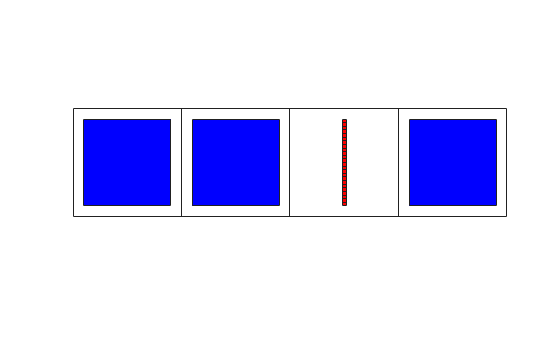

cellplot(c)

**Add data to cell array**

- Create/access entry with `{}`

- Assign contents of container with `= `

**Deleting data from cell array**

- Grab cell containers with `() `

- Delete containers by assigning the value `[]`

A = {}


A =

  0×0 empty cell array



day1 = grid(grid.Day==1,:);
day2 = grid(grid.Day==2,:);

A{1,1} = day1.DayName(1);
A{1,2} = max(day1.DemandMW);

A{2,1} = day2.DayName(1);
A{2,2} = max(day2.DemandMW);

A

A = 2×2 cell array
    {["Thu"]}    {[57505]}
    {["Fri"]}    {[55044]}


A{1,1} = [] % Clears the contents, but does NOT delete the cell

A = 2×2 cell array
    {0×0 double}    {[57505]}
    {["Fri"   ]}    {[55044]}


A(1,:) = [] % Deletes the entire first row of cells

A = 1×2 cell array
    {["Fri"]}    {[55044]}


**Combine Cell Arrays **

A = {day1.DayName(1), max(day1.DemandMW); ...
     day2.DayName(1), max(day2.DemandMW)};

B = {day1.DayName(1), max(day1.ForecastMW); ...
     day2.DayName(1), max(day2.ForecastMW)};

[A,B] % side-by-side: actual peak vs forecast peak

ans = 2×4 cell array
    {["Thu"]}    {[57505]}    {["Thu"]}    {[59519]}
    {["Fri"]}    {[55044]}    {["Fri"]}    {[58829]}


[A;B] % stack the two lists

ans = 4×2 cell array
    {["Thu"]}    {[57505]}
    {["Fri"]}    {[55044]}
    {["Thu"]}    {[59519]}
    {["Fri"]}    {[58829]}


### Comma-Separated List

- List of MATLAB objects separated by commas 

- Each item displayed individually when printed 

- Useful in passing arguments to functions and assigning output variables 

- Can be generated using `{:}` operator in cell array \

Int he below, we use `pstr{:}` because `plot` expects its options as **separate inputs**, not as a single cell array.

The `{:}` operator expands the contents of the cell array into a **comma-separated list**, so MATLAB treats them exactly as if we had typed `'LineWidth', 2` directly in the function call.

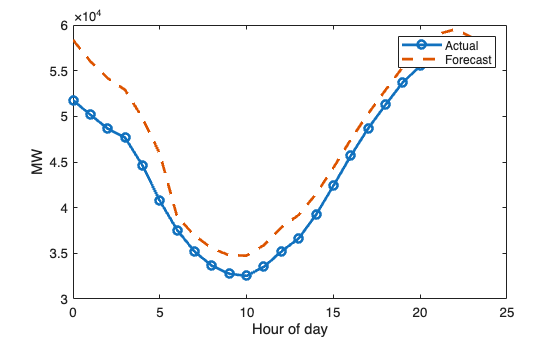

day1 = grid(grid.Day==1,:);
hr = hour(day1.Timestamp);

pstr = {'LineWidth',2};
plot(hr, day1.DemandMW,'-o', pstr{:}) % pass comma-separated list to plot
hold on
plot(hr, day1.ForecastMW,'--', pstr{:})
hold off
xlabel("Hour of day"), ylabel("MW")
legend("Actual","Forecast")

### Memory Requirements

Cell arrays require additional memory to store information describing each cell

- Information is stored in a header 

- Memory required for header of single cell

day1 = grid(grid.Day==1,:);
demand = day1.DemandMW;
whos demand

  Name         Size            Bytes  Class     Attributes

  demand      24x1               192  double              



demandCell = num2cell(demand);
whos demandCell

  Name             Size            Bytes  Class    Attributes

  demandCell      24x1              3072  cell               



**Key observations**

- `demand `is a single numeric array stored contiguously in memory (which means the information is stored next to each other on the chip)

- `demandCell `stores each value in a separate container

- Memory required for cell array: *head size x number of cells + data*

**Takeaway**: Cell arrays require additional memory because each cell stores bookkeeping information in addition to the data itself.

**Rule of thumb**

- Use **numeric arrays **when all elements have the same type and size

- Use **cell arrays **only when you need to store mixed types of variable-size data

Side note: storage is not necessarily contiguous **between **cells in array.

### Cell Array Functions

- `cell2mat` Convert cell array to numeric array 

- `cell2struct` Convert cell array to structure array 

- `cellfun` Apply function to each cell in cell array 

- `cellstr` Create cell array of strings from character array 

- `iscell` Determine whether input is cell array 

- `iscellstr` Determine whether input is cell array of strings 

- `mat2cell` Convert array to cell array 

- `num2cell` Convert array to cell array 

- `struct2cell` Convert structure to cell array 

% One cell per day: each cell holds a 24x1 vector of demand values
profiles = cell(1,7);
for k = 1:7
    profiles{k} = grid(grid.Day==k,:).DemandMW;
end

D = cell2mat(profiles)

D =        51756       55044       52732       52974       55512       57860       54385
       50171       52776       50673       50742       53679       55746       52647
       48655       50986       49028       48474       52057       54110       51754
       47667       49845       47940       46782       51238       52898       51032
       44629       46817       45385       44767       48381       49409       48208
       40754       43307       42470       42872       44766       45439       44611
       37547       40173       39566       40437       41716       42025       41550
       35199       37954       37379       38209       39612       39906       39577
       33637       36353       35757       36459       38216       38581       38291
       32759       35346       34698       35240       37343       37850       37544
       32536       34981       34057       34500       37325       37916       37545
       33527       35402       33939       34275       38482 

dailyPeak = cellfun(@max,profiles) % peak MW for each day

dailyPeak =        57505       55044       54755       56405       59930       57860       55243


dailyEnergy = cellfun(@sum,profiles) % MWh (recall that samples are hourly)

dailyEnergy =      1068283     1084390     1066050     1071403     1163471     1162069     1127191


num2cell(dailyPeak)

ans = 1×7 cell array
    {[57505]}    {[55044]}    {[54755]}    {[56405]}    {[59930]}    {[57860]}    {[55243]}


## Struct and Struct Arrays

A structure (struct) groups related data together using named fields.

- Each field has a **name** and a **value**

- Field values can be **any MATLAB type** (numeric arrays, cells, tables, etc.)

Think of a struct as a labeled container for related variables. Super high level idea: Use structs when your data has meaningful labels and use cells when you just need flexible storage.

You create or modify fields in a struct using **dot notation** with assignment. Writing `s.field = value` creates the field if it does not exist, or updates it if it already exists.

grid = readtable("/Users/winnicki/Documents/MATLAB/Lecture_01/gridDemandData.txt");

grid.DayName = string(grid.DayName);

day1 = grid(grid.Day == 1, :);

s = struct(); % empty struct
s.Day        = 1;
s.DayName    = day1.DayName(1);
s.Timestamp  = day1.Timestamp;
s.DemandMW   = day1.DemandMW;
s.ForecastMW = day1.ForecastMW;
s.PeakMW     = max(s.DemandMW);
s.EnergyMWh  = sum(s.DemandMW);
s

s = struct with fields:
           Day: 1
       DayName: "Thu"
     Timestamp: [24×1 datetime]
      DemandMW: [24×1 double]
    ForecastMW: [24×1 double]
        PeakMW: 57505
     EnergyMWh: 1068283


**Structure Array**

A **struct array** is an array where **each element is a struct with the same fields**.

week(1,7) = s;
for k = 1:7
    dayk = grid(grid.Day == k, :);
    week(k).Day        = k;
    week(k).DayName    = dayk.DayName(1);
    week(k).Timestamp  = dayk.Timestamp;
    week(k).DemandMW   = dayk.DemandMW;
    week(k).ForecastMW = dayk.ForecastMW;
    week(k).PeakMW     = max(dayk.DemandMW);
    week(k).EnergyMWh  = sum(dayk.DemandMW);
end
week(1)

ans = struct with fields:
           Day: 1
       DayName: "Thu"
     Timestamp: [24×1 datetime]
      DemandMW: [24×1 double]
    ForecastMW: [24×1 double]
        PeakMW: 57505
     EnergyMWh: 1068283


week(1).DemandMW

ans = 24×1
       51756
       50171
       48655
       47667
       44629
       40754
       37547
       35199
       33637
       32759
       32536
       33527
       35196
       36637
       39221


week(3).PeakMW

ans = 54755

**Nested structures **

Create and access nested structure array with multiple () and . syntax

grid = readtable("/Users/winnicki/Documents/MATLAB/Lecture_01/gridDemandData.txt");

grid.DayName = string(grid.DayName);

gridWeek(1).region = "ERCO (Texas)";

for k = 1:7
    dayk = grid(grid.Day==k,:);
    gridWeek(1).days(k).dayName = dayk.DayName(1);
    gridWeek(1).days(k).timestamps = dayk.Timestamp;
    gridWeek(1).days(k).demandMW = dayk.DemandMW;
    gridWeek(1).days(k).stats.peakMW = max(dayk.DemandMW);
    gridWeek(1).days(k).stats.meanMW = mean(dayk.DemandMW);
end

gridWeek(1).days(4).stats

ans = struct with fields:
    peakMW: 56405
    meanMW: 4.4642e+04


gridWeek(1).days(4)

ans = struct with fields:
       dayName: "Sun"
    timestamps: [24×1 datetime]
      demandMW: [24×1 double]
         stats: [1×1 struct]


### Memory Requirements

Structs require additional memory to store information

- Information is stored in a *header* 

- Header for entire structure array

Each field of a structure requires contiguous memory.

Storage is not necessarily contiguous between fields in structure or structures in array. 

Structure of arrays is faster/cheaper than array of structures.

- Contiguous memory, Memory overhead 

### Structure Functions

- `fieldnames` Field names of structure 

- `getfield` Field of structure array 

- `isfield` Determine whether input is structure field 

- `isstruct` Determine whether input is structure array 

- `orderfields` Order fields of structure array 

- `rmfield` Remove fields from structure 

- `setfield` Assign values to structure array field 

- `arrayfun` Apply function to each element of array 

- `structfun` Apply function to each field of scalar structure

# Tables

## Categorical arrays

Categorical variables are values from a finite set of discrete categories.

state = {'MA','ME','CT','VT','ME','NH','VT','MA','NH','CT','RI'}; 
state = categorical(state)

state = 1×11 categorical array
     MA      ME      CT      VT      ME      NH      VT      MA      NH      CT      RI 


Categories of categorical array

categories(state)

ans = 6×1 cell array
    {'CT'}
    {'MA'}
    {'ME'}
    {'NH'}
    {'RI'}
    {'VT'}


Count occurrences of categorical array elements by category

countcats(state)

ans = 1×6
     2     2     2     2     1     2


Group data into bins or categories

A = rand(10,1)

A = 10×1
    0.4218
    0.9157
    0.7922
    0.9595
    0.6557
    0.0357
    0.8491
    0.9340
    0.6787
    0.7577


discretize(A,linspace(0,1,5))

ans = 10×1
     2
     4
     4
     4
     3
     1
     4
     4
     3
     4


## Tables

Many data structures naturally have a tabular form.

Data entries can be organized as rows, each row containing the same number of fields.

MATLAB introduced tables in R2013b.

### Functions

- `head/tail` Get top/bottom rows of table 

- `summary` Print summary of table 

- `groupsummary` Group summary computations 

- `istable` Determine whether input is table 

- `(inner/outer)join` Combine two tables by rows using key variables 

- `readtable/writetable` Read/write table from/to file 

- `ismissing` Find missing values 

- `varfun` Apply function to table variables 

- `rowfun` Apply function to table rows 

- `splitapply` Split data into groups and apply function 

- `stackedplot` Stacked plot of several variables with common x-axis

grid = readtable("/Users/winnicki/Documents/MATLAB/Lecture_01/gridDemandData.txt");

grid.DayName = string(grid.DayName);

% Daily summary table (one row per day)
Day = (1:7)';
DayName = unique(grid.DayName,'stable');

PeakMW = zeros(7,1);
MeanMW = zeros(7,1);
for k = 1:7
    rows = grid.Day==k;
    PeakMW(k) = max(grid.DemandMW(rows));
    MeanMW(k) = mean(grid.DemandMW(rows));
end

T = table(Day, DayName, PeakMW, MeanMW, ...
    'VariableNames',["Day","DayName","PeakMW","MeanMW"]);

T.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Day'  'DayName'  'PeakMW'  'MeanMW'}
           VariableTypes: ["double"    "string"    "double"    "double"]
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


T.Properties.RowNames = cellstr(DayName);
T

T = 7×4 table
           Day    DayName    PeakMW    MeanMW
           ___    _______    ______    ______

    Thu     1      "Thu"     57505     44512 
    Fri     2      "Fri"     55044     45183 
    Sat     3      "Sat"     54755     44419 
    Sun     4      "Sun"     56405     44642 
    Mon     5      "Mon"     59930     48478 
    Tue     6      "Tue"     57860     48420 
    Wed     7      "Wed"     55243     46966 


% Join in a "weekday/weekend" label
DayType = categorical(["Weekday";"Weekday";"Weekend";"Weekend";"Weekday";"Weekday";"Weekday"]);
T2 = table(Day, DayType, 'VariableNames',["Day","DayType"]);
T = join(T2, T, 'Keys','Day')

T = 7×5 table
    Day    DayType    DayName    PeakMW    MeanMW
    ___    _______    _______    ______    ______

     1     Weekday     "Thu"     57505     44512 
     2     Weekday     "Fri"     55044     45183 
     3     Weekend     "Sat"     54755     44419 
     4     Weekend     "Sun"     56405     44642 
     5     Weekday     "Mon"     59930     48478 
     6     Weekday     "Tue"     57860     48420 
     7     Weekday     "Wed"     55243     46966 


### Timetables

- A special kind of table especially useful in scientific computing. 

- A specific time is associated with each row. Time is usually represented using `datetime` format (proleptic ISO calendar) 

- One can use all of table’s functions, as well as timetable specific functions.

#### Timetable Functions

- `timerange` Time range for timetable row subscripting 

- `retime` Resample or aggregate data in timetable 

- `synchronize` Synchronize timetables to common time vector 

- `istimetable` Determine whether input is timetable 

- `lag` Time-shift data in timetable 

- `withtol` Time tolerance for timetable row subscripting 

### Timetable Example

grid = readtable("/Users/winnicki/Documents/MATLAB/Lecture_01/gridDemandData.txt");

Remove DayName column

grid.DayName = []

grid = 168×4 table
    Day         Timestamp         DemandMW    ForecastMW
    ___    ___________________    ________    __________

     1     07/02/2015 00:00:00     51756        58359   
     1     07/02/2015 01:00:00     50171        56030   
     1     07/02/2015 02:00:00     48655        54174   
     1     07/02/2015 03:00:00     47667        52900   
     1     07/02/2015 04:00:00     44629        49820   
     1     07/02/2015 05:00:00     40754        45902   
     1     07/02/2015 06:00:00     37547        39000   
     1     07/02/2015 07:00:00     35199        36959   
     1     07/02/2015 08:00:00     33637        35548   
     1     07/02/2015 09:00:00     32759        34790   
     1     07/02/2015 10:00:00     32536        34749   
     1     07/02/2015 11:00:00     33527        35896   
     1     07/02/2015 12:00:00     35196      

Convert table to timetable, specify the second variable with dates and times, `Timestamp`, as the time vector of the timetable.

TT = table2timetable(grid,'RowTimes','Timestamp')

TT = 168×3 timetable
         Timestamp         Day    DemandMW    ForecastMW
    ___________________    ___    ________    __________

    07/02/2015 00:00:00     1      51756        58359   
    07/02/2015 01:00:00     1      50171        56030   
    07/02/2015 02:00:00     1      48655        54174   
    07/02/2015 03:00:00     1      47667        52900   
    07/02/2015 04:00:00     1      44629        49820   
    07/02/2015 05:00:00     1      40754        45902   
    07/02/2015 06:00:00     1      37547        39000   
    07/02/2015 07:00:00     1      35199        36959   
    07/02/2015 08:00:00     1      33637        35548   
    07/02/2015 09:00:00     1      32759     

istimetable(TT)

ans = logical
   1


summary(TT)


TT: 168×3 timetable

Row Times:

    Timestamp: datetime

Variables:

    Day: double
    DemandMW: double
    ForecastMW: double

Statistics for applicable variables and row times:

                  NumMissing              Min                      Median                       Max                       Mean                   Std      

    Timestamp         0           07/02/2015 00:00:00        07/05/2015 11:30:00        07/08/2015 23:00:00        07/05/2015 11:30:00        48:38:29    
    Day               0                             1                          4                          7                          4            2.0060  
    DemandMW          0                         32536                 4.6736e+04                      59930     

Specify a time range in July 2015

start_time = datetime('07/03/2015 00:00:00','InputFormat',"MM/dd/uuuu HH:mm:ss")

start_time = datetime
   03-Jul-2015


end_time = datetime('06-Jul-2015 00:00:00','InputFormat',"dd-MMM-uuuu HH:mm:ss")

end_time = datetime
   06-Jul-2015


S = timerange(start_time,end_time,"openright")

S = 	timetable timerange subscript:

		Select timetable rows with times in the half-open interval:
		  Starting at, including:   03-Jul-2015 00:00:00
		  Ending at, but excluding: 06-Jul-2015 00:00:00

	See Select Times in Timetable.


Select rows with times in the range specified by `S`.

TT2 = TT(S,:)

TT2 = 72×3 timetable
         Timestamp         Day    DemandMW    ForecastMW
    ___________________    ___    ________    __________

    07/03/2015 00:00:00     2      55044        57311   
    07/03/2015 01:00:00     2      52776        55059   
    07/03/2015 02:00:00     2      50986        53500   
    07/03/2015 03:00:00     2      49845        52166   
    07/03/2015 04:00:00     2      46817        49016   
    07/03/2015 05:00:00     2      43307        45108   
    07/03/2015 06:00:00     2      40173        39971   
    07/03/2015 07:00:00     2      37954        37656   
    07/03/2015 08:00:00     2      36353        35803   
    07/03/2015 09:00:00     2      35346     

Check if times are **regular**. The input is regular if its times are in a sequence that is strictly monotone (either increasing or decreasing) with a unique time step.

diff(TT2.Timestamp)

ans = 71×1 duration array
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00
   01:00:00


isregular(TT2)

ans = logical
   1


Shift the data forward in time by one time step and compare it to the original timetable.

TT3 = lag(TT2)

TT3 = 72×3 timetable
         Timestamp         Day    DemandMW    ForecastMW
    ___________________    ___    ________    __________

    07/03/2015 00:00:00    NaN       NaN          NaN   
    07/03/2015 01:00:00      2     55044        57311   
    07/03/2015 02:00:00      2     52776        55059   
    07/03/2015 03:00:00      2     50986        53500   
    07/03/2015 04:00:00      2     49845        52166   
    07/03/2015 05:00:00      2     46817        49016   
    07/03/2015 06:00:00      2     43307        45108   
    07/03/2015 07:00:00      2     40173        39971   
    07/03/2015 08:00:00      2     37954        37656   
    07/03/2015 09:00:00      2     36353     

Synchronize the two timetables for comparison.

synchronize(TT2,TT3)

ans = 72×6 timetable
         Timestamp         Day_TT2    DemandMW_TT2    ForecastMW_TT2    Day_TT3    DemandMW_TT3    ForecastMW_TT3
    ___________________    _______    ____________    ______________    _______    ____________    ______________

    07/03/2015 00:00:00       2          55044            57311           NaN           NaN              NaN     
    07/03/2015 01:00:00       2          52776            55059             2         55044            57311     
    07/03/2015 02:00:00       2          50986            53500             2         52776            55059     
    07/03/2015 03:00:00       2          49845            52166             2         50986           

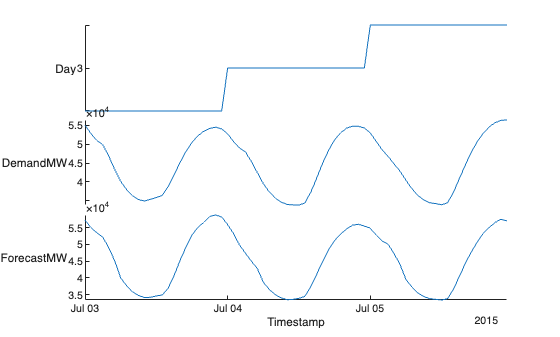

stackedplot(TT2);

#### *More on data visualization later...*

# Function and Function Handle

### Scripts vs. Functions

**Scripts **

- Execute a series of MATLAB statements 

- Uses base workspace (does not have own workspace) 

- Parsed and loaded into memory every execution 

**Functions** 

- Accept inputs, execute a series of MATLAB statements, and return outputs 

- Local workspace defined only during execution of function: `global, persistent` variables and `evalin, assignin` commands help share variables between workspaces or allow them to persist between function executions. More info at [https://www.mathworks.com/help/matlab/matlab_prog/share-data-between-workspaces.html](https://www.mathworks.com/help/matlab/matlab_prog/share-data-between-workspaces.html). 

- Local, nested, private, anonymous, class methods 

- Parsed and loaded into memory during first execution

### Anonymous Functions

Functions not stored in a program file, but associated with a variable

- Stored directly in function handle 

- Store expression and require variables 

- Zero or more arguments allowed 

- Nested anonymous functions permitted 

- Only a single executable statement

f1 = @(x,y) [sin(pi*x), cos(pi*y), tan(pi*x*y)];
f1(0.5,0.25)

ans = 1×3
    1.0000    0.7071    0.4142


Array of function handle not allowed; function handle may return array

integral(@(x) exp(1)*x.^2,-1,1)

ans = 1.8122

### Local Functions

A given MATLAB file can contain multiple functions 

The first function is the **main** function 

- Callable from anywhere, provided it is in the search path 

Other functions in file are local functions 

- Only callable from main function or other local functions in same file 

- Enables modularity (large number of small functions) without creating a large number of files 

- Unfavorable from code reusability standpoint

### Nested Functions 

A nested function is a function completely contained within some parent function. 

Useful as an alternative to anonymous function that can’t be confined to a single line 

Can’t be defined within MATLAB control statements `if/elseif/else, switch/case, for, while, `or` try/catch `

Variables sharable between parent and nested functions 

If variable in nested function is not used in parent function, it remains local to the nested function 

Multiple levels of nesting is permitted. Nested function available from:

- Level immediately above 

- Function nested at same level with same parent 

- Function at any lower level 

Ex. n`ested_ex.m`

### Private Functions 

Private functions are useful for limiting the scope of a function 

Designate a function as private by storing it in a subfolder named private 

Only available to functions/scripts in the folder immediately above the private subfolder

### Evaluate/Assign in Another Workspace

Evaluate expression in other workspace ('`caller`', '`base`') 

- `evalin(ws,expression) `

- Useful for evaluating expression in caller’s workspace without passing name variables as function arguments

a = evalin('base','2+3')

a = 5

Assign variable in other workspace ('`caller`', '`base`') 

- `assignin(ws, 'var', val) `

- Useful for circumventing local scope restrictions of functions

assignin('base','b','hello')
b

b = 'hello'

### Variable Number of Inputs/Outputs

Query number of inputs passed to a function 

- `nargin` 

- Don’t try to pass more than in function declaration 

Determine number of outputs requested from function 

- `nargout` 

- Don’t request more than in function declaration

nargin(@cat)

ans = -1

Input-output argument list length unknown or conditional 

- Think of plot, get, set and the various Name-Property pairs that can be specified in a given function call 

Use `varargin` as last function input and `varargout` as last function output for input/output argument lists to be of variable length

All arguments prior to `varargin/varargout` will be matched one-to-one with calling expression 

Remaining input/outputs will be stored in a cell array named `varargin/varargout`

Ex.` vararg_ex.m`

[b,vo1,vo2,vo3,vo4] = vararg_ex(2,'variable','input/output','example','!')

b = 4

vo1 = 'variable'

vo2 = 'input/output'

vo3 = 'example'

vo4 = '!'

[b,~] = vararg_ex(3,'variable','input/output')

b = 9

## Function Handle (`@`)

Callable association to MATLAB function stored in variable 

- Enables invocation of function outside its normal scope 

- Invoke function indirectly 

- Variable

Capture data for later use

Enables passing functions as arguments 

- Optimization 

- Solution of nonlinear systems of equations 

- Solution of ODEs 

- Numerical Integration

Function handles must be scalars, i.e. can’t be indexed with` ()`

Example at the end of the live script file.

#### Example of function handle: Trapezoidal rule for integration


$$\int_a^b f\left(x\right)\mathrm{dx}\approx \sum_{i=1}^n \frac{b-a}{2n}\left\lbrack f\left(x_{i-\frac{1}{2}} \right)+\left(x_{i+\frac{1}{2}} \right)\right\rbrack$$
 

a = exp(1);
f = @(x) a*x.^2;
trap_rule(f,-1,1,1000)

ans = 1.8122

**Trapezoidal rule for integration function**

You may also create a function file `trap_rule.m` first, using the code in this section.

function int_f = trap_rule(f,a,b,n)
    x=linspace(a,b,n+1)';
    int_f=0.5*((b-a)/n)*sum(f(x(1:end-1))+f(x(2:end)));
end